% Clear variables, figures
clear;
clf;
clc;
% Open Simulink model
open('humanSubject07_48dof_test.slx');

% Human arm parameters

% Number of DoF
arm.n = 7;

% Shoulder
arm.shoulder.length = 0.47828; % [m]
arm.shoulder.radius = 0.02877; % [m]
arm.shoulder.mass = 2.4459; % [Kg]
arm.shoulder.moment_inertia = [0.0059341, 0.0010123, 0.0059341]; % [Kg*m^2]

% Forearm
arm.forearm.length = 0.2584; % [m]
arm.forearm.radius = 0.022803; % [m]
arm.forearm.mass = 1.578; % [Kg]
arm.forearm.moment_inertia = [0.0089856, 0.00041027, 0.0089856]; % [Kg*m^2]

% Hand
arm.hand.dimensions = [0.12916, 0.19374, 0.045607]; % [m]
arm.hand.mass = 0.4734; % [Kg]
arm.hand.moment_inertia = [0.0015629, 0.0007401900000000001, 0.0021389]; % [Kg*m^2]

% Markers
arm.markers.radius = 0.01; % [m]
marker.M_BaseRF = [arm.shoulder.radius+arm.markers.radius -3/4*arm.shoulder.length 0;
                   -arm.shoulder.radius-arm.markers.radius -3/4*arm.shoulder.length 0;
                   arm.shoulder.radius+arm.markers.radius -1/4*arm.shoulder.length 0;
                   -arm.shoulder.radius-arm.markers.radius -1/4*arm.shoulder.length 0;
                   arm.forearm.radius+arm.markers.radius -3/4*arm.forearm.length 0;
                   -arm.forearm.radius-arm.markers.radius -1/2*arm.forearm.length 0;
                   arm.forearm.radius+arm.markers.radius -1/4*arm.forearm.length 0;
                   0 -3/4*arm.hand.dimensions(2) arm.hand.dimensions(3)/2+arm.markers.radius;
                   0 -1/4*arm.hand.dimensions(2) arm.hand.dimensions(3)/2+arm.markers.radius];
marker.links = [1;
                1;
                1;
                1;
                2;
                2;
                2;
                3;
                3];
marker.m = height(marker.M_BaseRF); % Number of markers

% Align Reference frames
align.Rx = [1 0 0;
            0 0 -1;
            0 1 0];
align.Ry = [0 0 1;
            0 1 0;
            -1 0 0];
align.Rz = [0 -1 0;
            1 0 0;
            0 0 1];

% Noise
noise.sampleTime = 0.01;
noise.p_var = 0.00001 * ones(marker.m * 3, 1);
noise.p_seed = 1;
noise.pdot_seed = 2;

# LS APPROACH


$$\dot{q} = J^{\dagger}(q) \cdot  \dot{p}  \qquad \longrightarrow \qquad $$


#### FORWARD KINEMATICS


$$\pmatrix{p_{1} \cr P_{2} \cr .. \cr P_{M}} = \pmatrix{\Phi_1(q) \cr \Phi_2(q) \cr ..  \cr \Phi_M(q) } \qquad \Longrightarrow \qquad  p = \Phi(q)$$


#### JACOBIAN COMPUTATION


$$\pmatrix{\dot{p}_{1} \cr \dot{p}_{2} \cr .. \cr \dot{p}_{M}} = \pmatrix{J_1(q) \cr J_2(q) \cr ..  \cr J_M(q) } \cdot \dot{q} \qquad \Longrightarrow \qquad  \dot{p} = J(q) \cdot  \dot{q} $$


## 1.  PERFECT GUESS OF INITIAL CONDITION q0 

% Initial CORRECT joint variables estimate used by LS
LS.q0 = [0;
         0;
         0;
         0;
         0;
         0;
         0];

###       1.1 SMALLER NOISE vs LARGER NOISE affecting pdot

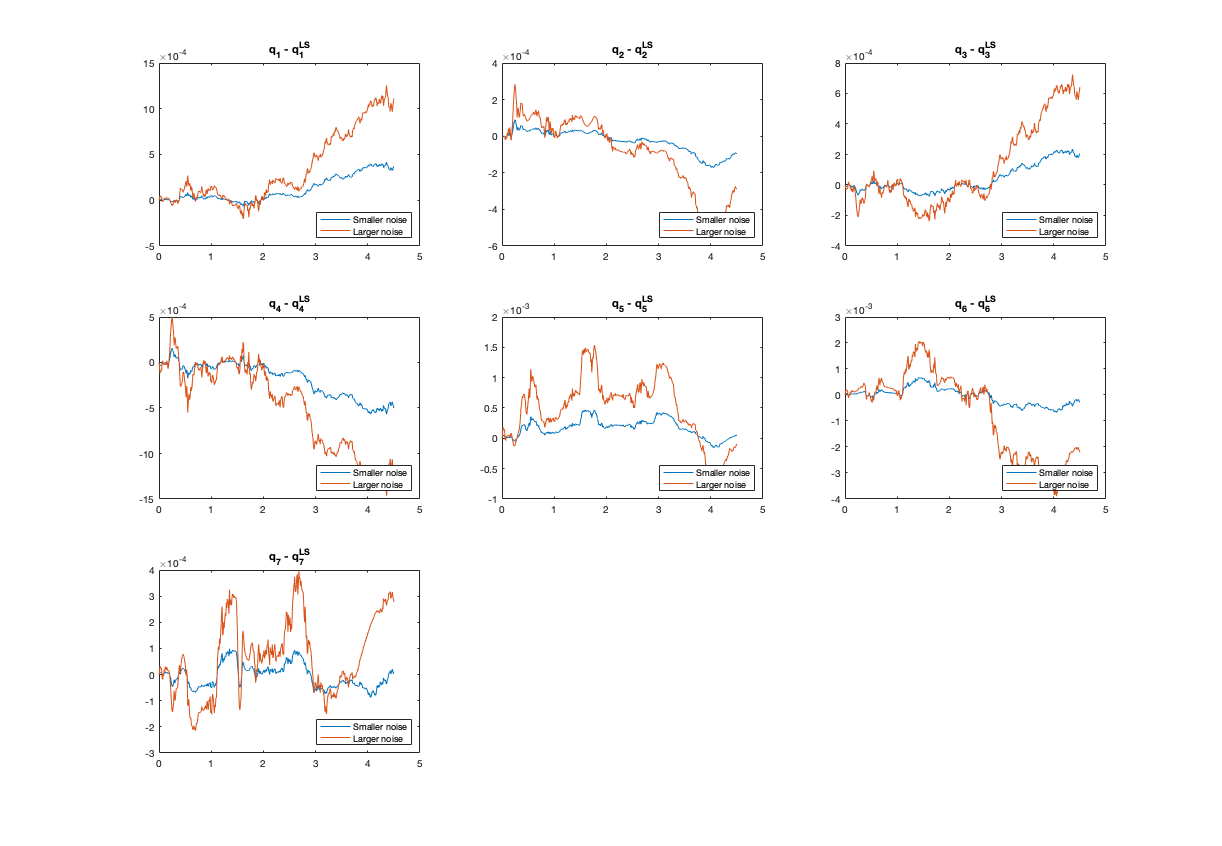

% Noise affecting pdot measurements
noise.pdot_var = 0.0000001 * ones(marker.m * 3, 1);

% Simulation
output_1 = sim("humanSubject07_48dof_test.slx");

% Noise affecting pdot measurements
noise.pdot_var = 0.000001 * ones(marker.m * 3, 1);

% Simulation
output_2 = sim("humanSubject07_48dof_test.slx");

% Plot error between q_LS and q (comparison between smaller noise and larger noise)
title_name = cell(arm.n, 1);
fig_1 = figure(1);
for i = 1 : arm.n

    title_name{i} = strcat('q_', num2str(i), ' - q_', num2str(i), '^{LS}');
    set(fig_1, 'position', [10, 10, 1300, 900]);
    subplot(3,3,i);
    plot(output_1.q.time, output_1.q.signals.values(:, i) - squeeze(output_1.q_LS.signals.values(i, :))');
    hold on;
    plot(output_2.q.time, output_2.q.signals.values(:, i) - squeeze(output_2.q_LS.signals.values(i, :))');
    legend('Smaller noise', 'Larger noise', 'Location', 'southeast');
    title(title_name{i});
end

## 2.  WRONG GUESS OF INITIAL CONDITION q0

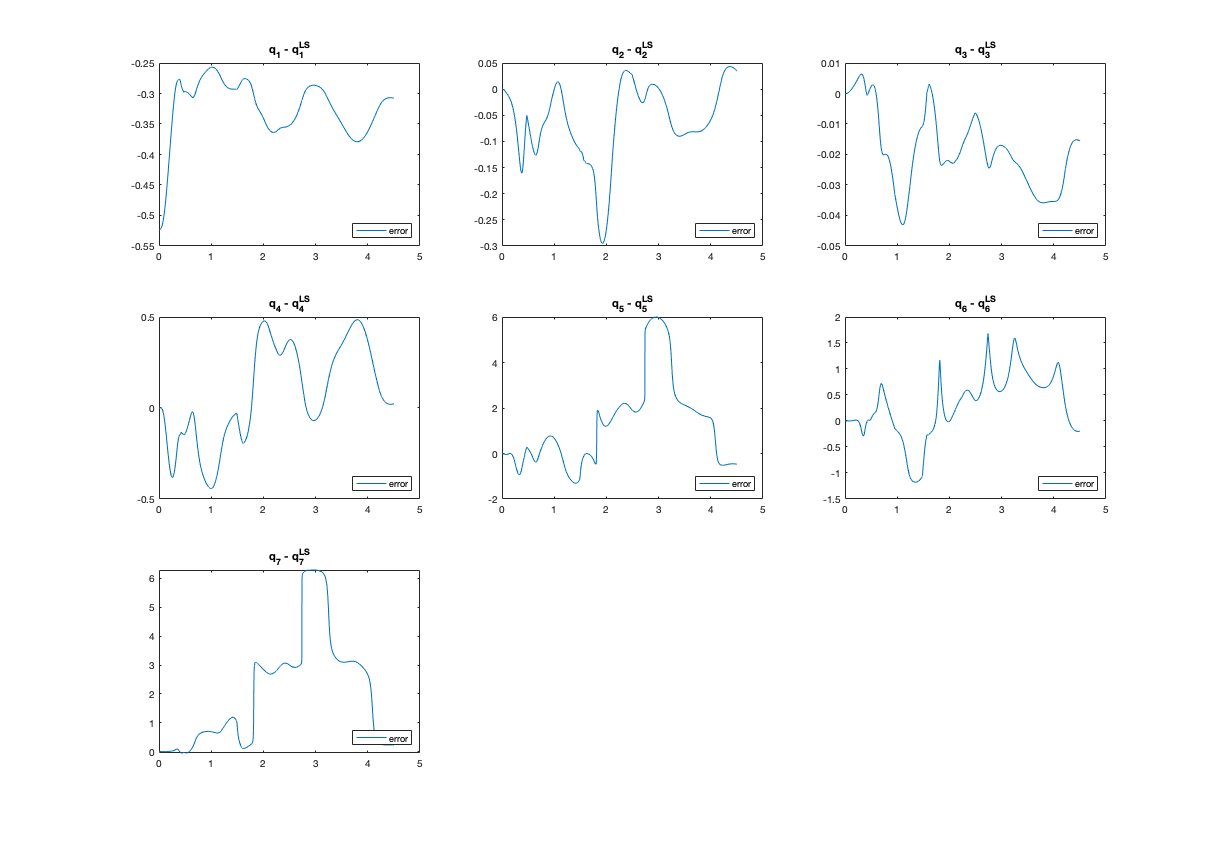

% Initial WRONG joint variables estimate used by LS
LS.q0 = [pi/6;
         0;
         0;
         0;
         0;
         0;
         0];

% Noise affecting pdot measurements
noise.pdot_var = 0.0000001 * ones(marker.m * 3, 1);

% Simulation
output_3 = sim("humanSubject07_48dof_test.slx");

% Plot error between q_LS and q
fig_3 = figure(3);
for i = 1 : arm.n

    title_name{i} = strcat('q_', num2str(i), ' - q_', num2str(i), '^{LS}');
    set(fig_3, 'position', [10, 10, 1300, 900]);
    subplot(3,3,i);
    plot(output_3.q.time, output_3.q.signals.values(:, i) - squeeze(output_3.q_LS.signals.values(i, :))');
    legend('error', 'Location', 'southeast');
    title(title_name{i});
end